# UMAP exploration!

Set paths

addpath /Users/elie/Documents/CODE/umap_1.4.1/umap
addpath /Users/elie/Documents/CODE/umap_1.4.1/util
javaaddpath('/Users/elie/Documents/CODE/umap_1.4.1/umap/umap.jar')

load('/Users/elie/Documents/CODE/LMC/explore_populationSU_data_5000.mat')

NC = size(KDE_onset_Mat_BaTr_ZS,1);
ResampleFactor = 10;
Test = resample(KDE_onset_Mat_BaTr_ZS(1,:), 1,ResampleFactor);
KDE_onset_Mat_BaTr_ZS_RS = nan(size(KDE_onset_Mat_BaTr_ZS,1),size(Test,2));
for cc=1:NC
    KDE_onset_Mat_BaTr_ZS_RS(cc,:) = resample(KDE_onset_Mat_BaTr_ZS(cc,:), 1,ResampleFactor);
end
fprintf(1,'\n\n ***** Distance Euclidean resampled data *****\n')



 ***** Distance Euclidean resampled data *****


n\_neighbors=\color{blue}30\color{black}, min\_dist=\color{blue}0.3\color{black}, metric=\color{blue}euclidean\color{black},randomize=\color{blue}0\color{black}, labels=\color{blue}0


UMAP(method=Java, n_neighbors=30, n_components=2, metric=euclidean, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, random_state=true, metric_kwds=[], target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]
Elapsed time is 0.012726 seconds.


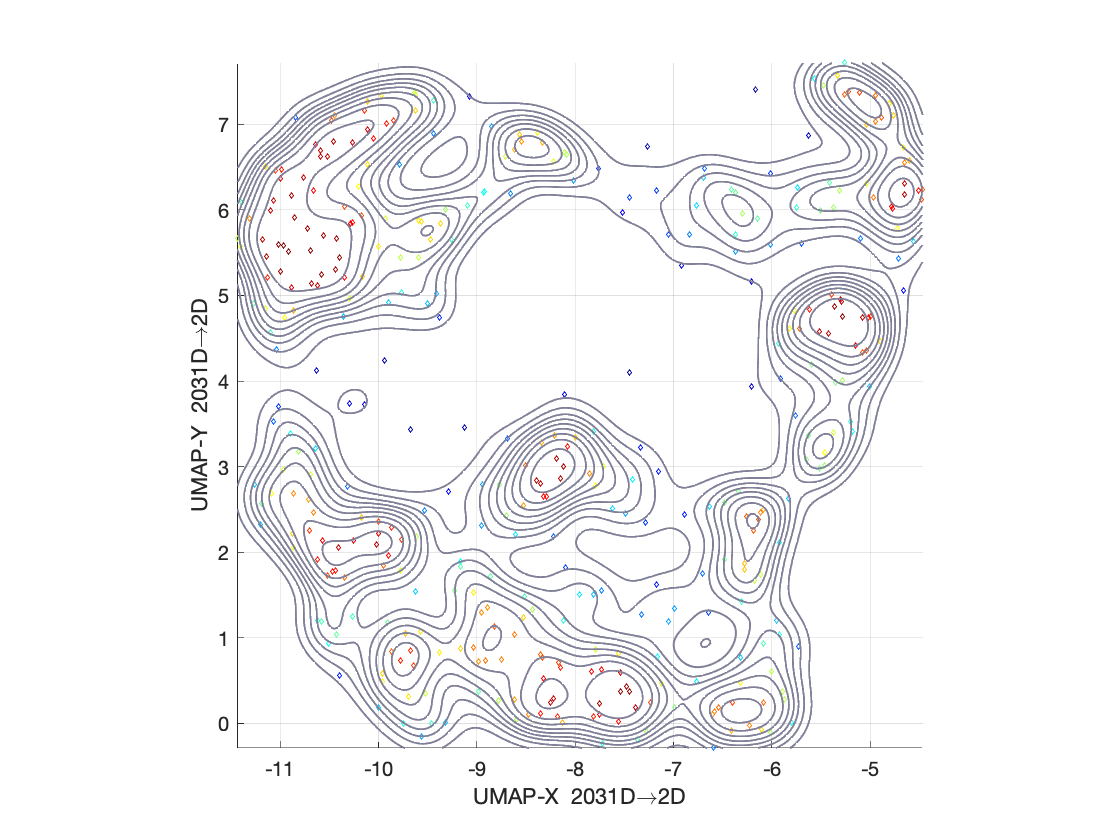

Error using matlab.graphics.shape.TextBox/set
Invalid or deleted object.

Error in run_umap (line 855)
    set(paramAnnotation, 'visible', 'on');

[Reduction,UMAP,ClustID]= run_umap(KDE_onset_Mat_BaTr_ZS_RS);

fprintf(1,'\n\n ***** Distance Euclidean *****\n')



 ***** Distance Euclidean *****


n\_neighbors=\color{blue}30\color{black}, min\_dist=\color{blue}0.3\color{black}, metric=\color{blue}euclidean\color{black},randomize=\color{blue}0\color{black}, labels=\color{blue}0


UMAP(method=Java, n_neighbors=30, n_components=2, metric=euclidean, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, random_state=true, metric_kwds=[], target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]
Elapsed time is 0.010951 seconds.


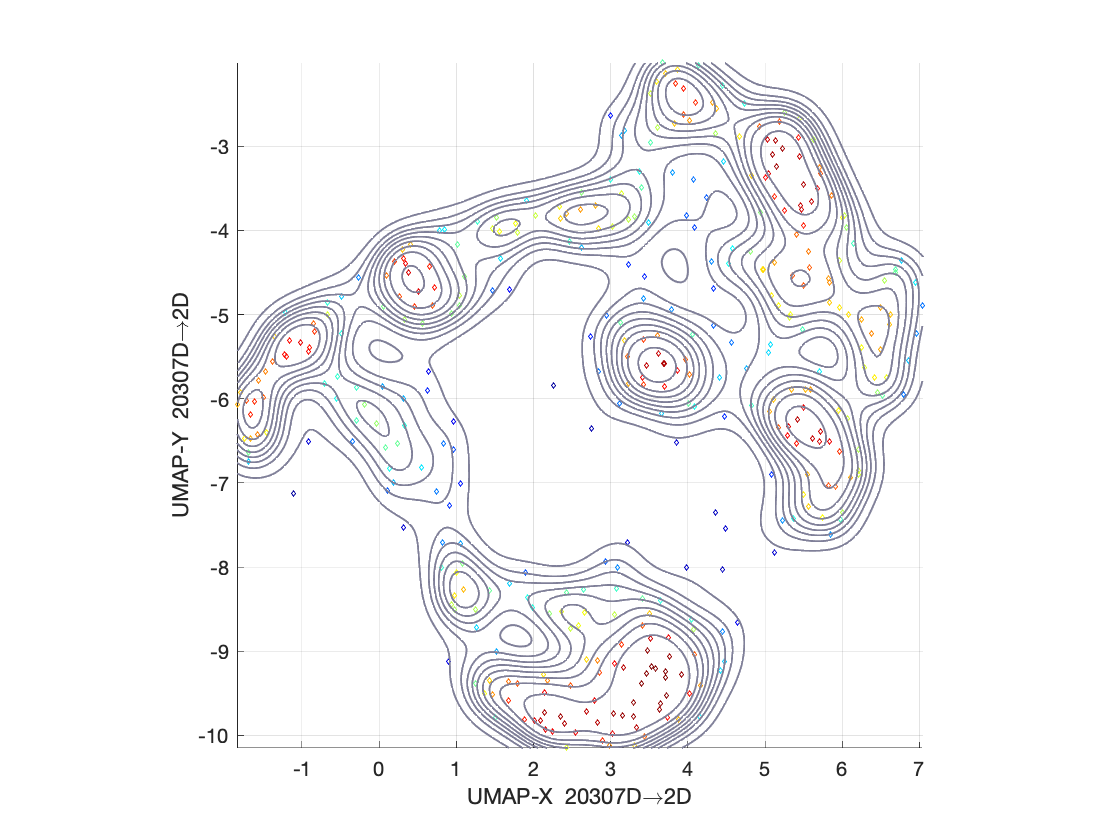

Error using matlab.graphics.shape.TextBox/set
Invalid or deleted object.

Error in run_umap (line 855)
    set(paramAnnotation, 'visible', 'on');

[Reduction,UMAP,ClustID]= run_umap(KDE_onset_Mat_BaTr_ZS);

fprintf(1,'\n\n ***** Distance Cosine *****\n')



 ***** Distance Cosine *****


n\_neighbors=\color{blue}30\color{black}, min\_dist=\color{blue}0.3\color{black}, metric=\color{blue}cosine\color{black},randomize=\color{blue}0\color{black}, labels=\color{blue}0


UMAP(method=Java, n_neighbors=30, n_components=2, metric=cosine, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, random_state=true, metric_kwds=[], target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='cosine', dist_args=[]


Elapsed time is 0.013724 seconds.


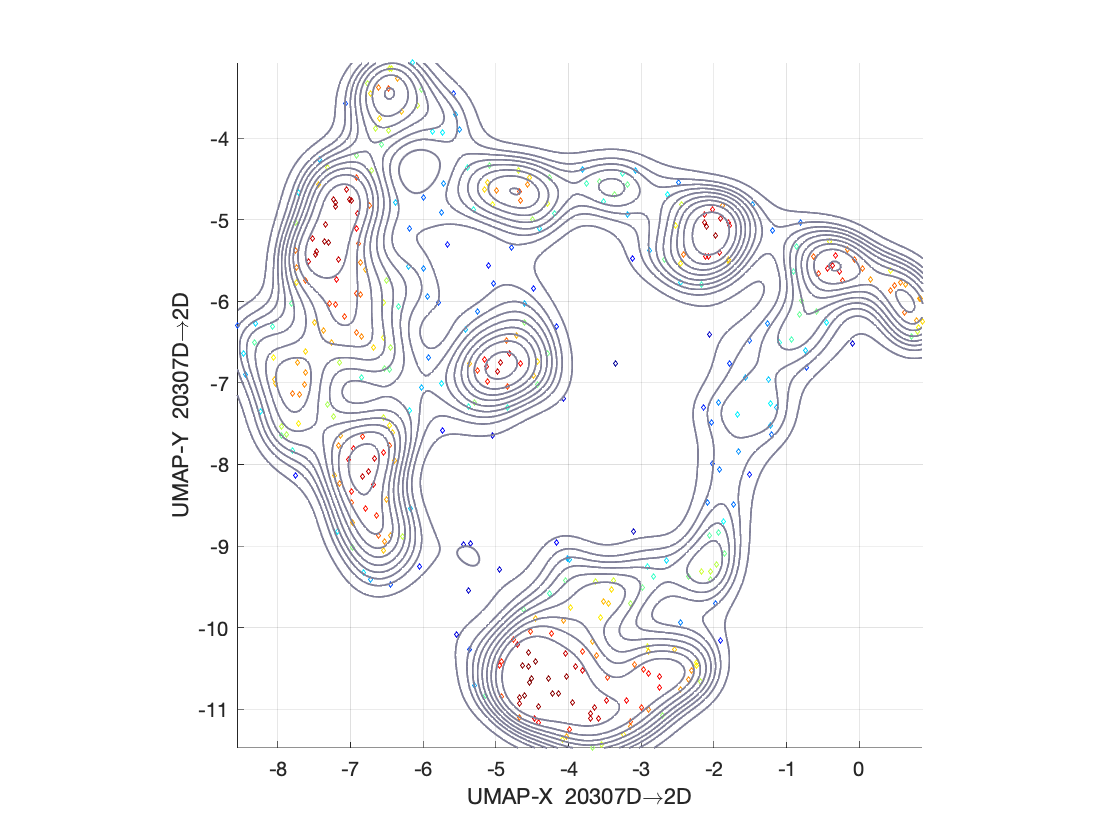

Error using matlab.graphics.shape.TextBox/set
Invalid or deleted object.

Error in run_umap (line 855)
    set(paramAnnotation, 'visible', 'on');

[Reduction,UMAP,ClustID]= run_umap(KDE_onset_Mat_BaTr_ZS,'metric','cosine');

fprintf(1,'\n\n ***** Distance correlation *****\n')



 ***** Distance correlation *****


n\_neighbors=\color{blue}30\color{black}, min\_dist=\color{blue}0.3\color{black}, metric=\color{blue}correlation\color{black},randomize=\color{blue}0\color{black}, labels=\color{blue}0


UMAP(method=Java, n_neighbors=30, n_components=2, metric=correlation, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, random_state=true, metric_kwds=[], target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='correlation', dist_args=[]
Elapsed time is 0.010676 seconds.


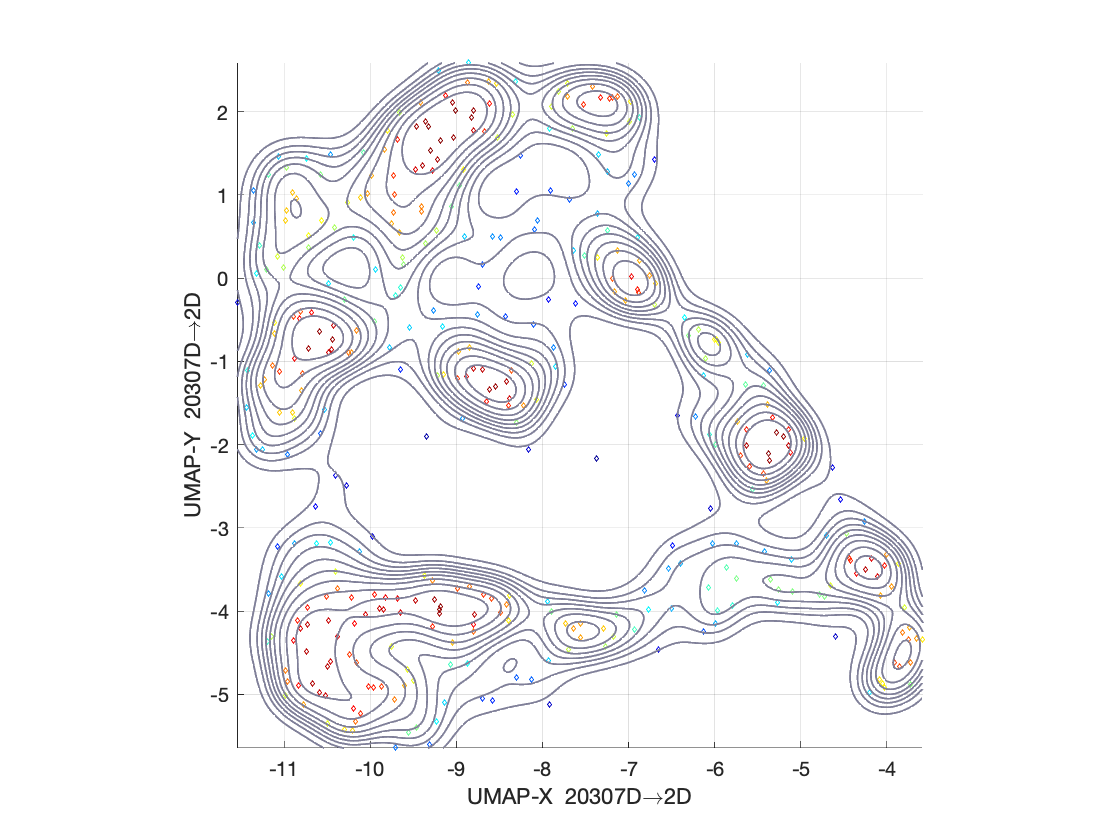

Error using matlab.graphics.shape.TextBox/set
Invalid or deleted object.

Error in run_umap (line 855)
    set(paramAnnotation, 'visible', 'on');

[Reduction,UMAP,ClustID]= run_umap(KDE_onset_Mat_BaTr_ZS,'metric','correlation');

fprintf(1,'\n\n ***** Distance Jaccard *****\n')



 ***** Distance Jaccard *****


n\_neighbors=\color{blue}30\color{black}, min\_dist=\color{blue}0.3\color{black}, metric=\color{blue}jaccard\color{black},randomize=\color{blue}0\color{black}, labels=\color{blue}0


UMAP(method=Java, n_neighbors=30, n_components=2, metric=jaccard, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, random_state=true, metric_kwds=[], target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='jaccard', dist_args=[]
Elapsed time is 0.006262 seconds.


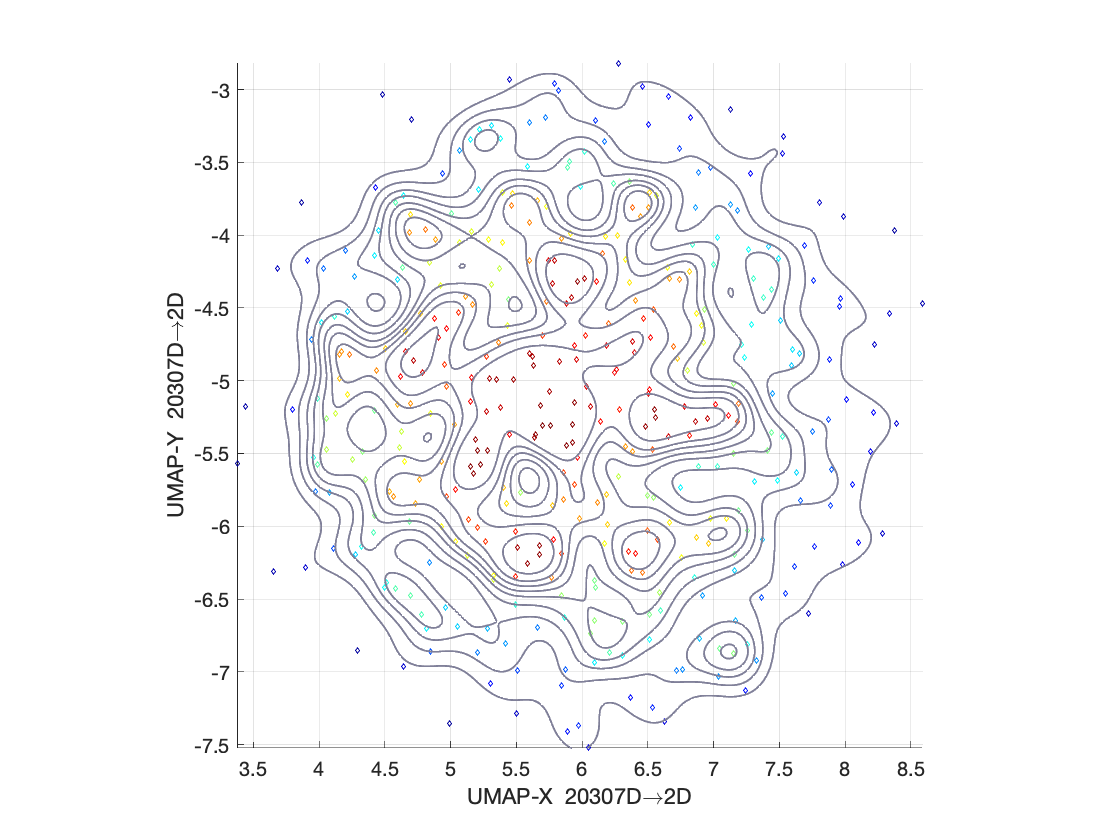

Error using matlab.graphics.shape.TextBox/set
Invalid or deleted object.

Error in run_umap (line 855)
    set(paramAnnotation, 'visible', 'on');

[Reduction,UMAP,ClustID]= run_umap(KDE_onset_Mat_BaTr_ZS,'metric','jaccard');

fprintf(1,'\n\n ***** Distance Spearman *****\n')



 ***** Distance Spearman *****


n\_neighbors=\color{blue}30\color{black}, min\_dist=\color{blue}0.3\color{black}, metric=\color{blue}spearman\color{black},randomize=\color{blue}0\color{black}, labels=\color{blue}0


UMAP(method=Java, n_neighbors=30, n_components=2, metric=spearman, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, random_state=true, metric_kwds=[], target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='spearman', dist_args=[]
Elapsed time is 0.011395 seconds.


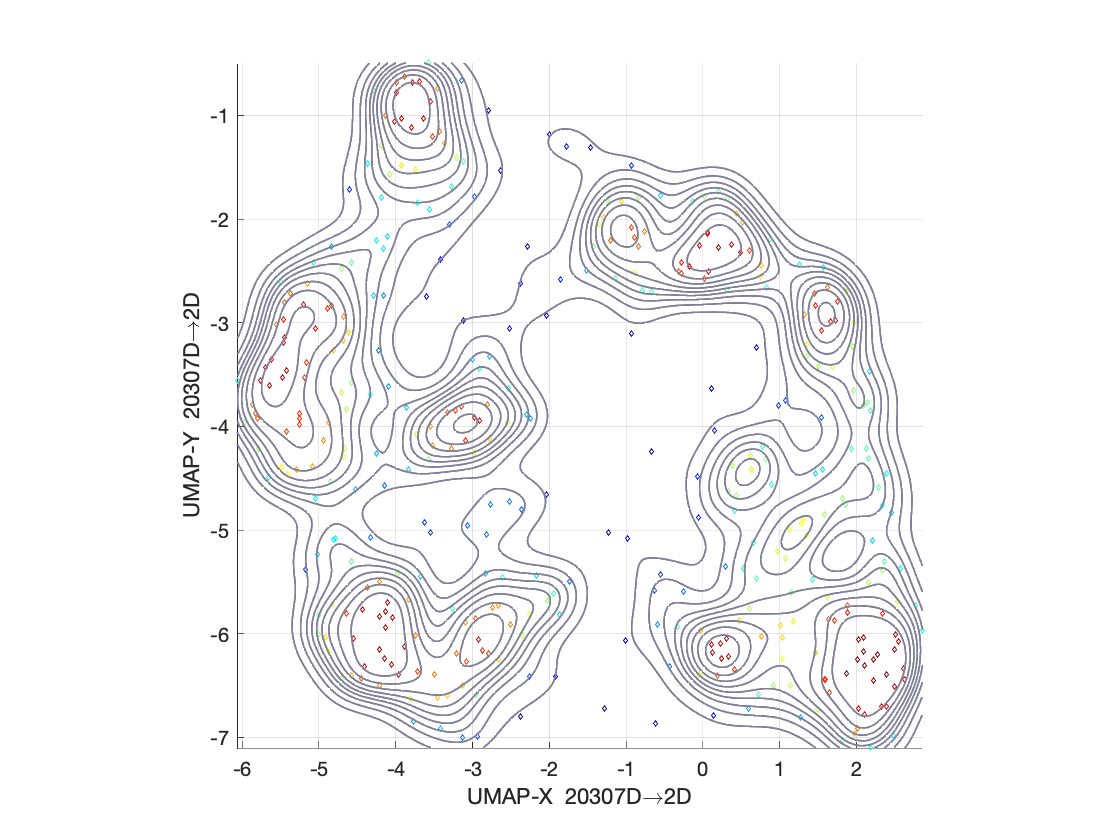

Error using matlab.graphics.shape.TextBox/set
Invalid or deleted object.

Error in run_umap (line 855)
    set(paramAnnotation, 'visible', 'on');

[Reduction,UMAP,ClustID]= run_umap(KDE_onset_Mat_BaTr_ZS,'metric','spearman');

fprintf(1,'\n\n ***** Distance Hamming *****\n')



 ***** Distance Hamming *****


n\_neighbors=\color{blue}30\color{black}, min\_dist=\color{blue}0.3\color{black}, metric=\color{blue}hamming\color{black},randomize=\color{blue}0\color{black}, labels=\color{blue}0


UMAP(method=Java, n_neighbors=30, n_components=2, metric=hamming, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, random_state=true, metric_kwds=[], target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='hamming', dist_args=[]
Elapsed time is 0.005326 seconds.


Error using matlab.graphics.shape.TextBox/set
Invalid or deleted object.

Error in run_umap (line 855)
    set(paramAnnotation, 'visible', 'on');

[Reduction,UMAP,ClustID]= run_umap(KDE_onset_Mat_BaTr_ZS,'metric','hamming');